clear variables

date_data = '20230117'; %as string
trl_num = '12'; %as string, vicon
batID = 'bat05';  %as string
train_or_test = 'Testing';  %as string
cond = 'blank';%as string, experiment condition
luminescence = ' Dark'; % as string, 
landing = 'blank'; % as string,
flight_trajectory ='blank'; % as string,
release = 'blank'; % as string,
notes ='none';
trl_name = strjoin({batID,'_',date_data,'_',cond,'_',trl_num});
trl_name = strrep(trl_name, ' ', ''); % Remove spaces

is_approach_1_present = 1;  % Set to 0 if not present
is_inspect_present = 0;     % Set to 0 if not present
is_approach_2_present = 1;  % Set to 0 if not present

adjust_approach_1_start_frames = 0; % Adjust Approach 1 start time by adding or subtracting frames
adjust_approach_1_end_frames = 0;
adjust_inspect_start_frames = 0;    % Adjust Inspect start time by adding or subtracting frames
adjust_inspect_end_frames = 0;      % Adjust Inspect end time by adding or subtracting frames
adjust_approach_2_start_frames = 0; % Adjust Approach 2 start time by adding or subtracting frames
adjust_approach_2_end_frames= 0;   % Adjust Approach 2 end time by adding or subtracting frames

f =   Figure (1: Flight Trajectory) with properties:

      Number: 1
        Name: 'Flight Trajectory'
       Color: [1 1 1]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


approach_1_end_indices = 278

Click Rate during Approach 1: 11.8705 clicks per second


Click Rate during Approach 2: 7.0988 clicks per second


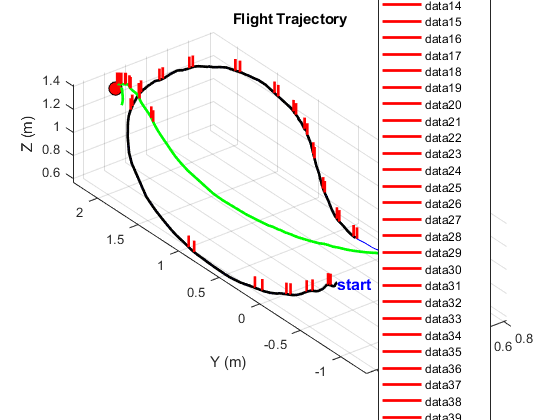

Total Click Rate: 7.1250 clicks per second


click_data = process_flight_data (date_data, trl_num,cond,trl_name, batID, train_or_test, cond, luminescence, landing, flight_trajectory, release, notes, is_approach_1_present, is_inspect_present, is_approach_2_present, adjust_approach_1_start_frames, adjust_approach_1_end_frames, adjust_inspect_start_frames, adjust_inspect_end_frames, adjust_approach_2_start_frames, adjust_approach_2_end_frames);